# EPC 7 - Estatística Aplicada

## João Gabriel Santos Custodio, n° 08 

## Atividade 1: Fazer um gráfico de controle para média, desvio padrão e range, usando 500 primeiras amostras de x1 para n =5 e para n=20.

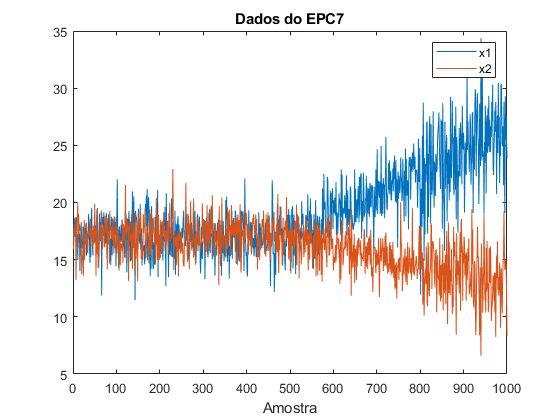

% Caminho para os arquivos
FILE_path_1 = 'dados_epc7_x1_corr.txt';
FILE_path_2 = 'dados_epc7_x2_corr.txt';
% importação dos dados
dados1 = readmatrix(FILE_path_1);
dados2 = readmatrix(FILE_path_2);
n_id = 8; % Número na chamada
% Segmentação dos dados para somente a coluna 8
x1 = dados1(:, n_id);
% 500 primeiras amostras 
x2 = dados2(:, n_id);

figure
plot(1:1:1000,x1)
hold on
plot(1:1:1000,x2)
title("Dados do EPC7")
legend("x1","x2")
xlabel("Amostra")

n = 5;
m = 500/n;

% 500 primeiras amostras 
x1_1_500 = x1(1:500);

% cria uma matriz de dimensão mxn
matrix_m_n = zeros(m,n);
% cria um vetor de dimensão mx1
vetor_x_barra = zeros(m,1);
% cria um vetor mx1
vetor_r = zeros(m,1);
% cria um vetor mx1
vetor_s = zeros(m,1);

% Loop responsável por iterar dentro do vetor contendo as primeiras 500
% amostras
for i = 1:1:m
    % Vetor n que percorre as amostras de n em n por loop
    % ex: i = 1, vet_n = (1:5); i=2 vet_n = (6:10)...
    vetor_n = x1_1_500(n*i-(n-1):n*i); 
    x_barra = mean(vetor_n);
    r = max(vetor_n) - min(vetor_n);
    s = std(vetor_n);
   vetor_x_barra(i) = x_barra;
   vetor_r(i) = r;
   vetor_s(i) = s;
   matrix_m_n(i,:) = vetor_n;
end

Cálculo das "m" médias:

x1_barrra_barra = mean(vetor_x_barra) % 

x1_barrra_barra = 17.0062

r_barra  = max(vetor_r) - min(vetor_r)

r_barra = 6.8780

s_barra   = std(vetor_s)

s_barra = 0.6003

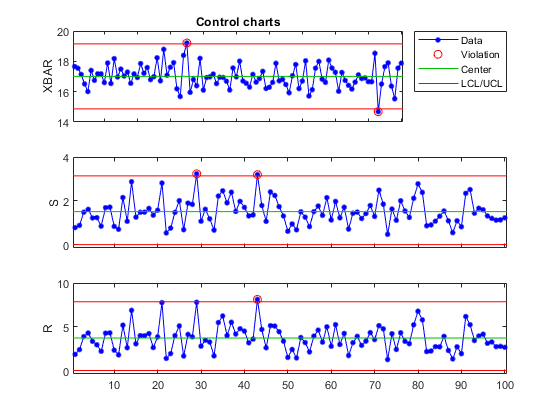

controlchart(matrix_m_n,'charttype',{'xbar' 's' 'r'})

A seguir, temos uma função que reitera o cálculo feito anteriormente, em conjunto com a tabela de coeficientes presente no livro, para construir os gráficos de controle estatístico. Isso é realizado por meio das equações que estabelecem os valores de UCL, CL e LCL.

x_barra:

S:

R:

E também a tabela de coeficientes:

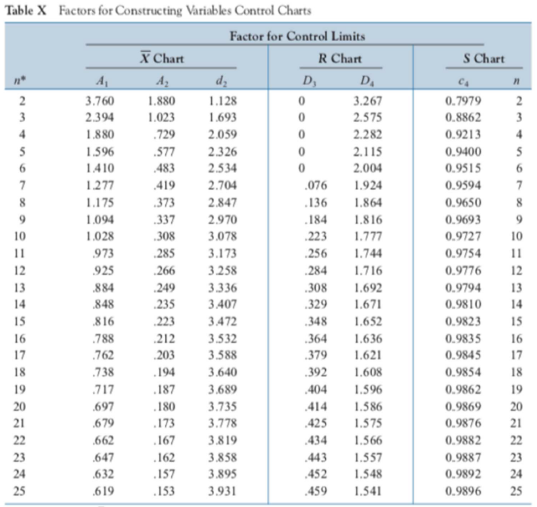

Com isso, podemos calcular o gráfico de X_barra, S e R:

controlchart(matrix_m_n,'charttype',{'xbar' 's' 'r'})

A seguir, repete-se os procedimentos para n=20:

n = 20;
m = 500/n;

% 500 primeiras amostras 
x1_1_500 = x1(1:500);

% cria uma matriz de dimensão mxn
matrix_m_n = zeros(m,n);
% cria um vetor de dimensão mx1
vetor_x_barra = zeros(m,1);
% cria um vetor mx1
vetor_r = zeros(m,1);
% cria um vetor mx1
vetor_s = zeros(m,1);

% Loop responsável por iterar dentro do vetor contendo as primeiras 500
% amostras
for i = 1:1:m
    % Vetor n que percorre as amostras de n em n por loop
    % ex: i = 1, vet_n = (1:5); i=2 vet_n = (6:10)...
    vetor_n = x1_1_500(n*i-(n-1):n*i); 
    x_barra = mean(vetor_n);
    r = max(vetor_n) - min(vetor_n);
    s = std(vetor_n);
   vetor_x_barra(i) = x_barra;
   vetor_r(i) = r;
   vetor_s(i) = s;
   matrix_m_n(i,:) = vetor_n;
end


x1_barrra_barra = mean(vetor_x_barra) % 

x1_barrra_barra = 17.0062

r_barra  = max(vetor_r) - min(vetor_r)

r_barra = 5.3867

s_barra   = std(vetor_s)

s_barra = 0.3235

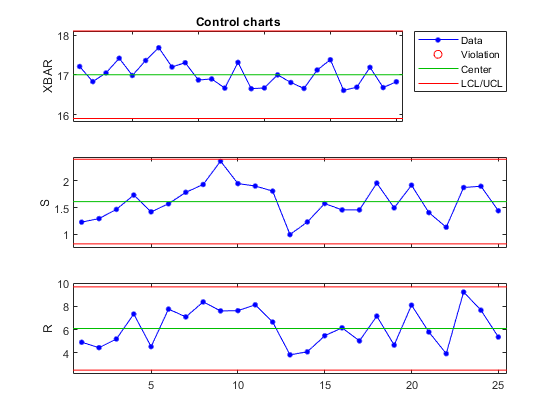

controlchart(matrix_m_n,'charttype',{'xbar' 's' 'r'})

A partir dos gráficos, fica evidente que para um processo que visa-se verificação de qualidade estatística, tende-se a ter um melhor aproveitamente quando opta-se por uma menor quantidade de amostras por subgrupo, pois o aumento do numero de amostras há uma tendencia de mascarar um subgrupo que fique fora do contole estatísco.

## Atividade 2) Escolher n para otimizar o desempenho das métricas recall e TD dos gráficos de controle para média, desvio padrão e range.

valoresn =      2     4     5    10    20    25    50   100
